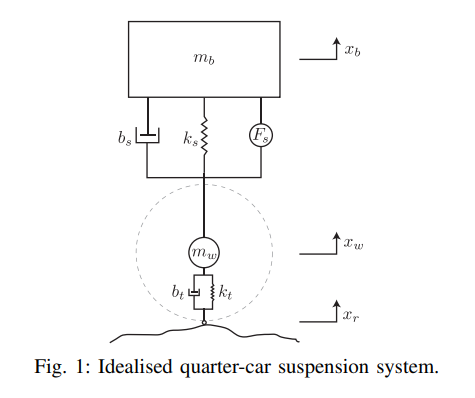

We use the above quater car mode with the following parameters


$$m_b =450\;\textrm{kg};k_b =13000\;\frac{N}{m};$$

$$b_s =1100\;\frac{\textrm{Ns}}{s}$$



$$m_w =70\;\textrm{kg};k_t =140,000\;\frac{N}{m};b_t =755\;\frac{\textrm{Ns}}{m}$$



$$x_r =x_{\textrm{r0}\;} \sin \left(\textrm{wt}\right)$$


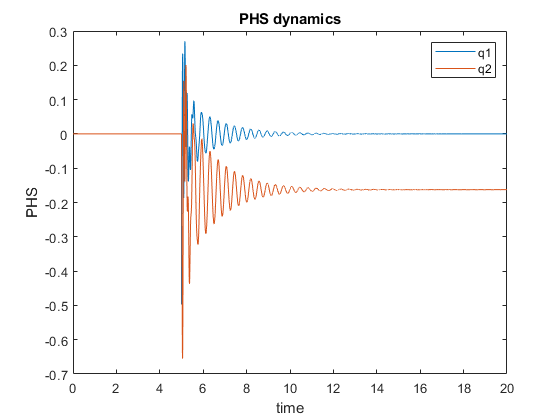

clc
clear
close all

tfinal = 20; dt = 0.001; % simulation parameters


mb=2.45; ks=980; bs=7.5;
mw=1; kt=2500; bt=5;
M = [mw+mb mb;mb mb];
G1 = [bt;0]; G2 = [-1;0]; 
D = diag([bt,bs]); G = [0;1];
A_hat = [-D -eye(2);eye(2) zeros(2)];
B_hat = [G;zeros(2,1)];

lambda = -1; % convergence rate for control law

xr = 0; xr0 = xr;
x0 = [0;0;0;0]; x = x0; t = 0; H_sys = 0; 
p10 = mb*x(2); p1 = p10; p20 = mw*x(4); p2 = p20; p=[p1;p2];
q10 = x(1); q1 = q10; q20 = x(3); q2 = q20; q=[q1;q2];
xw = q10 + xr0; xb = q20 + xw;
p_hat = p - G1*xr0; q_hat = q - G2*xr0;
phs0 = [p_hat;q_hat]; phs = phs0; % initial conditions

PHS = []; T = []; 
Q = [];P = [];
Xb = []; Xw = []; Xr = []; % initialize memory

while (t <= tfinal)
    T = [T,t]; PHS = [PHS,phs];
    Q = [Q,q]; P = [P,p]; 
    Xb = [Xb,xb]; Xw = [Xw,xw]; Xr = [Xr,xr];

    if(t>5)
        xr = 0.5;
    else
        xr = 0;
    end

    K = [0.5*p_hat(1)+bt*xr; 0.5*p_hat(2)];
    KE_hat = K'*inv(M)*K;
    PE_hat = 0.5*kt*(q_hat(1)-xr)^2 + 0.5*ks*q_hat(2)^2;
    H_hat = KE_hat + PE_hat; %total energy

    u = lambda*(H_hat)/2; %control law
    phs = phs + dt*(A_hat*([inv(M)*[phs(1)+bt*xr;phs(2)];(kt*(phs(3)-xr));phs(4)*ks]) + B_hat*u); %diff eqn
    
    %recover original coordinates
    q = [phs(3);phs(4)]+G2*xr; 
    p = [phs(1);phs(2)]+G1*xr;
    xw = q(1) + xr;
    xb = q(2) + xw;

    t = t + dt; % time increment
end

figure(1)
plot(T,Q);
ylabel('PHS')
xlabel('time')
legend('q1','q2')
title('PHS dynamics')

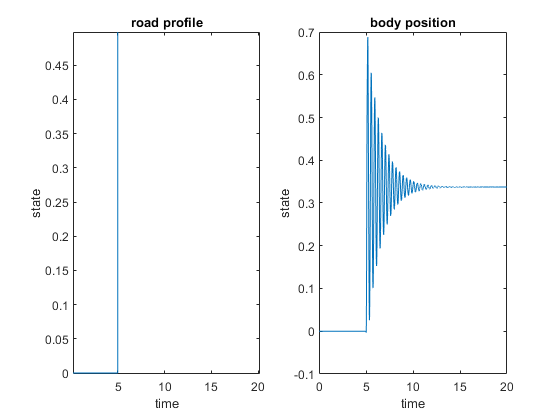

figure(2)
title('position dynamics')
subplot(1,2,1)
plot(T,Xr); hold on;
title('road profile')
ylabel('state')
xlabel('time')
subplot(1,2,2)
%plot(T,Xw); hold on;
plot(T,Xb);
ylabel('state')
xlabel('time')
title('body position')


hold off

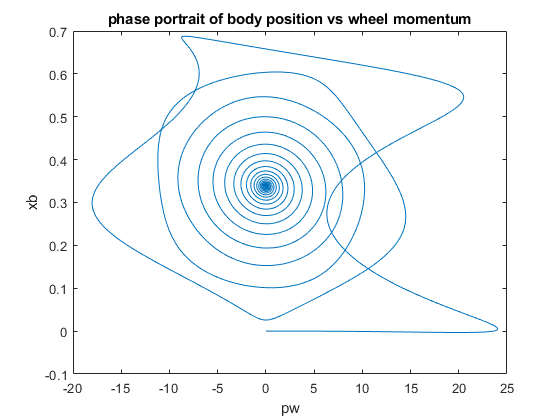

figure(3)
plot(P(1,:),Xb); hold on;
ylabel('xb')
xlabel('pw')
title('phase portrait of body position vs wheel momentum')
hold off